clearvars

### INIT PARAM:

% Init param
% Definim N i M
M = 7;
M_values = zeros(M, 1);
for i = 1:length(M_values)
    M_values(i) = 2^i;  
end

num_points = 21;
M_values = floor(2.^linspace(1,9,num_points)) % Array de 2 a 512

M_values =      2     2     3     4     6     8    10    13    18    24    32    42    55    73    97   128   168   222   294   388   512



N_values = zeros(20, 1);
for j = 1:length(N_values)
    N_values(j) = j;  
end


% Fem grid
[M_grid, N_grid] = meshgrid(M_values, N_values);

%% SNR + rho
SNR = 1.0;
current_rho = 0.5;

% Matriu per desar els temps d'execució
T_elapsed_1 = zeros(length(N_values), length(M_values));  % Files: N, Columnes: M
T_elapsed_2 = zeros(length(N_values), length(M_values));  % Files: N, Columnes: M
total_time = zeros(length(N_values), length(M_values));  % Files: N, Columnes: M

### COMPUTACIÓ TEMPS F0 (per separat)

%% F0 i primera derivada
for col = 1:length(M_values)
    % Generem simbols i probs per Mi
    [x, q] = PAM_generator(M_values(col));
    for row = 1:length(N_values)
        % Generem cuadratura i pesos per Ni
        [z, w] = GaussHermite_Locations_Weights(N_values(row));
        % Matrius
        [Q, pi_, G] = matrix_generator(N_values(row), q, x, w, z, SNR);
        
        tic;                                        % Time starts
        F0_val = F0_F0p(Q, pi_, G, current_rho);
        elapsed_time = toc;                         % Time ends
        
        % Desem temps en la matriu
        T_elapsed_1(row, col) = elapsed_time;
    end
    fprintf('%d M=%d\n', col, M_values(col));
end

1 M=2
2 M=2
3 M=3
4 M=4
5 M=6
6 M=8
7 M=10
8 M=13
9 M=18
10 M=24
11 M=32
12 M=42
13 M=55
14 M=73
15 M=97
16 M=128
17 M=168
18 M=222
19 M=294
20 M=388
21 M=512


%% F0 i les seves primera i segona derivada
for col = 1:length(M_values)
    % Generem simbols i probs per Mi
    [x, q] = PAM_generator(M_values(col));
    for row = 1:length(N_values)
        % Generem cuadratura i pesos per Ni
        [z, w] = GaussHermite_Locations_Weights(N_values(row));
        % Matrius
        [Q, pi_, G] = matrix_generator(N_values(row), q, x, w, z, SNR);
        
        tic;                                        % Time starts
        F0_val = F0_matrix_fixed(Q, pi_, G, current_rho);
        elapsed_time = toc;                         % Time ends
        
        % Desem temps en la matriu
        T_elapsed_2(row, col) = elapsed_time;
    end
    fprintf('%d M=%d\n', col, M_values(col));
end

1 M=2
2 M=2
3 M=3
4 M=4
5 M=6
6 M=8
7 M=10
8 M=13
9 M=18
10 M=24
11 M=32
12 M=42
13 M=55
14 M=73
15 M=97
16 M=128
17 M=168
18 M=222
19 M=294
20 M=388
21 M=512


### GRÀFICS

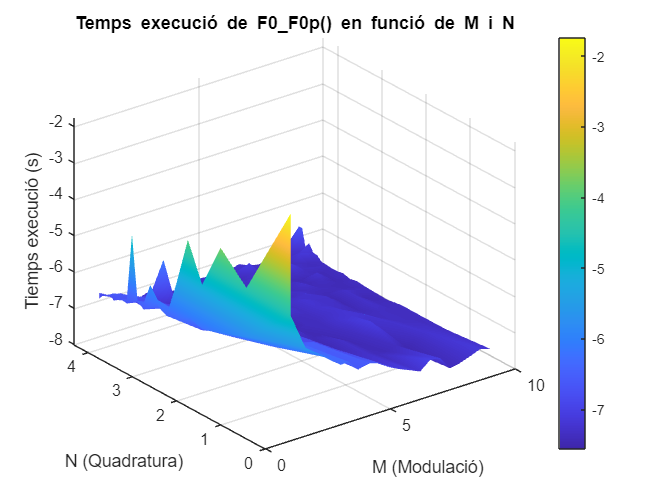

%% Grafic pla - T_elapsed_1: F0 i primera derivada
figure;
% Grid 
T = T_elapsed_1 ./ ((M_grid).^2.* N_grid.^2);
surf(log2(M_grid), log2(N_grid), log10(T));
shading interp; 
colormap(parula);
colorbar;
xlabel('M (Modulació)');
ylabel('N (Quadratura)');
zlabel('Tiemps execució (s)');
title('Temps execució de F0\_F0p() en funció de M i N');
grid on;

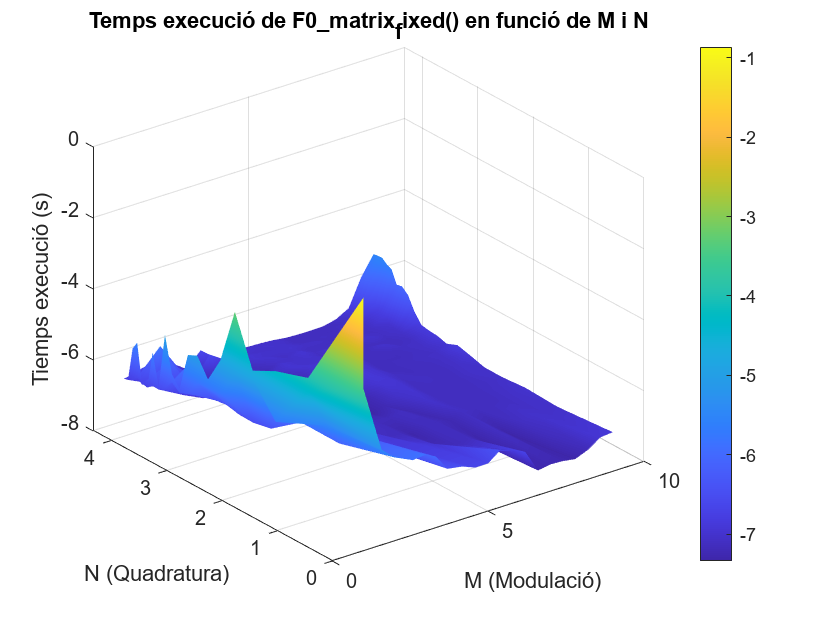

%% Grafic pla - T_elapsed_1: F0, primera i segona derivada
figure;
% Grid 
T = T_elapsed_2 ./ ((M_grid).^2.* N_grid.^2);
surf(log2(M_grid), log2(N_grid), log10(T));
shading interp; 
colormap(parula);
colorbar;
xlabel('M (Modulació)');
ylabel('N (Quadratura)');
zlabel('Tiemps execució (s)');
title('Temps execució de F0\_matrix_fixed() en funció de M i N');
grid on;

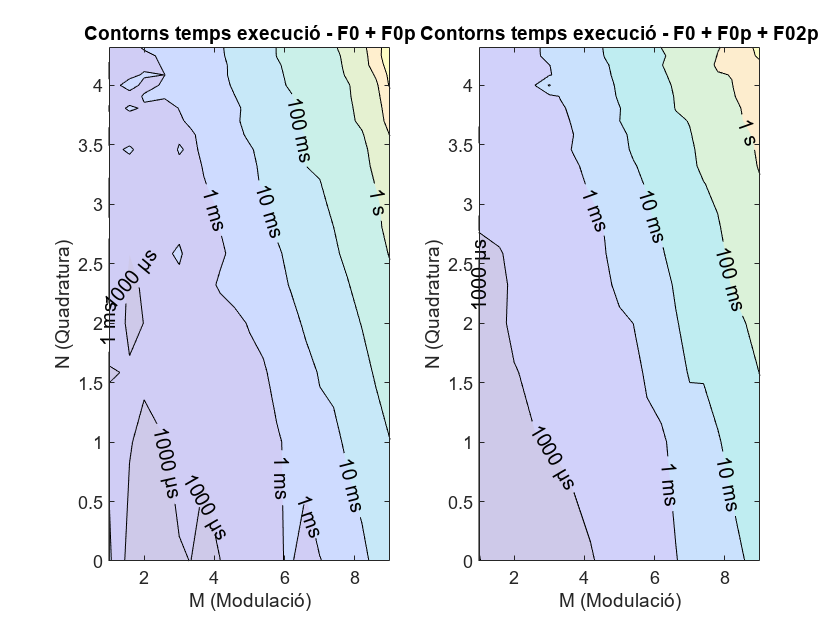

%% Graficar líneas de contorno - F0 & F0p
figure;
subplot(1,2,1);
T = log10(T_elapsed_2);
contourf(log2(M_grid), log2(N_grid), T, -10:10, 'ShowText', true, ...
    'LabelFormat',@mylabelfun, ...
    'FaceAlpha',0.25);
xlabel('M (Modulació)');
ylabel('N (Quadratura)');
title('Contorns temps execució - F0 + F0p');

%% Graficar líneas de contorno - F0 & F0p & F02p
subplot(1,2,2);
T = log10(T_elapsed_1);
contourf(log2(M_grid), log2(N_grid), T, -10:10, 'ShowText', true, ...
    'LabelFormat',@mylabelfun, ...
    'FaceAlpha',0.25);
xlabel('M (Modulació)');
ylabel('N (Quadratura)');
title('Contorns temps execució - F0 + F0p + F02p');

### **TEMPS TOTAL:**

% FUNCIÓ QUE ET DIU EL TEMPS TOTAL D'UTILITZAR NEWTON:
% Example
M = 8;
N = 6;
example = estimated_time(5, 6, T_elapsed_1, T_elapsed_2);

%% F0 i les seves primera i segona derivada
for col = 1:length(M_values)
    for row = 1:length(N_values)
        total_time(row, col) = estimated_time(col, row, T_elapsed_1, T_elapsed_2);   
    end
    fprintf('%d M=%d\n', col, M_values(col));
end

1 M=2
2 M=2
3 M=3
4 M=4
5 M=6
6 M=8
7 M=10
8 M=13
9 M=18
10 M=24
11 M=32
12 M=42
13 M=55
14 M=73
15 M=97
16 M=128
17 M=168
18 M=222
19 M=294
20 M=388
21 M=512


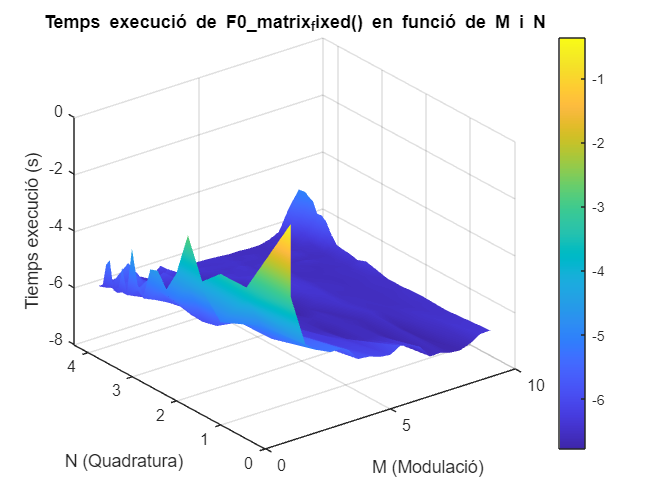

%% Grafic pla - Temps total
figure;
% Grid 
T = total_time ./ ((M_grid).^2.* N_grid.^2);
surf(log2(M_grid), log2(N_grid), log10(T));
shading interp; 
colormap(parula);
colorbar;
xlabel('M (Modulació)');
ylabel('N (Quadratura)');
zlabel('Tiemps execució (s)');
title('Temps execució de F0\_matrix_fixed() en funció de M i N');
grid on;

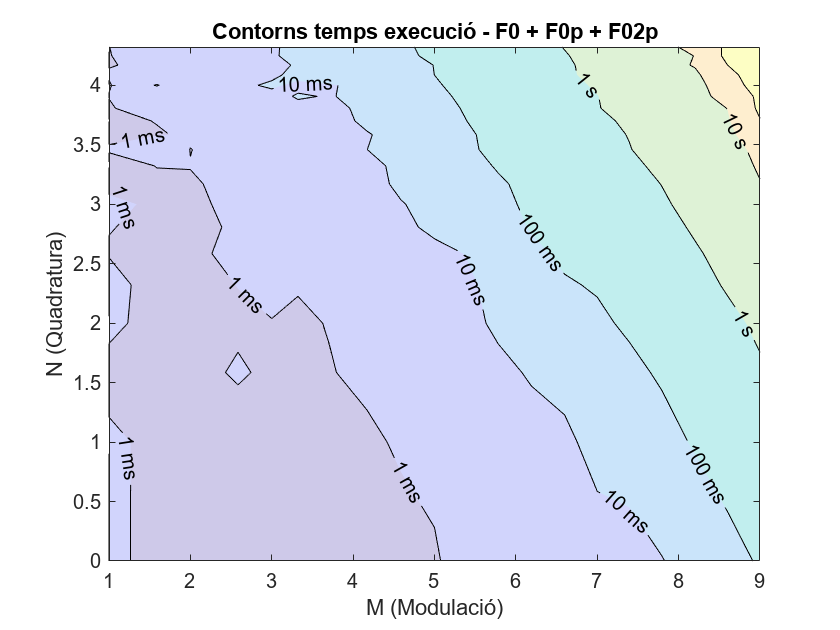

%% Graficar líneas de contorno - Temps total
figure;
T = log10(total_time);
contourf(log2(M_grid), log2(N_grid), T, -10:10, 'ShowText', true, ...
    'LabelFormat',@mylabelfun, ...
    'FaceAlpha',0.25);
xlabel('M (Modulació)');
ylabel('N (Quadratura)');
title('Contorns temps execució - F0 + F0p + F02p');

### FUNCIONS

function labels = mylabelfun(vals)
    labels = string.empty;
    for i = 1:length(vals)
        switch vals(i)
            case 2
                labels(i) = '100 s';
            case 0
                labels(i) = '1 s';
            case 1
                labels(i) = '10 s';
            case 3
                labels(i) = '1000 s';
            case -1
                labels(i) = '100 ms';
            case -2
                labels(i) = '10 ms';
            case -3
                labels(i) = '1 ms';
            case -4
                labels(i) = '1000 μs';
            otherwise
                labels(i) = '??';      
        end
    end

end

%% TOTAL TIME
function time = estimated_time(M_pos, N, time1, time2)
    %M_pos = log2(M);
    t_init = time1(N, M_pos);
    t_matrix = time2(N, M_pos);
    % Amb el newton method sabem que només arriba a fer fins a 3
    % iteracions, per tant, el total time he decidit que sera aixi (segons el meu criteri :) )
    time = t_init + 3*t_matrix;
end